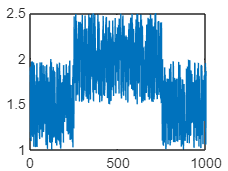

% Senal creada random
ref_signal = ones(1000,1)+rand(1000,1);
ref_signal(250:750) = ref_signal(250:750)+0.5;
plot(ref_signal)

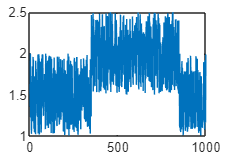

% Senal de referencia con cambio de fase (desplazamiento)
new_signal = rand(1000,1)+1;
new_signal(100:1000) = ref_signal(1:901);
plot(new_signal)

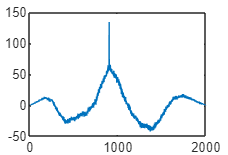

% Correlacion entre ambas senales
corout = xcorr(ref_signal-mean(ref_signal),new_signal-mean(new_signal));
plot(corout)